# Gradient Descent

Consider this relation between two variables, $x$ and $y$. 

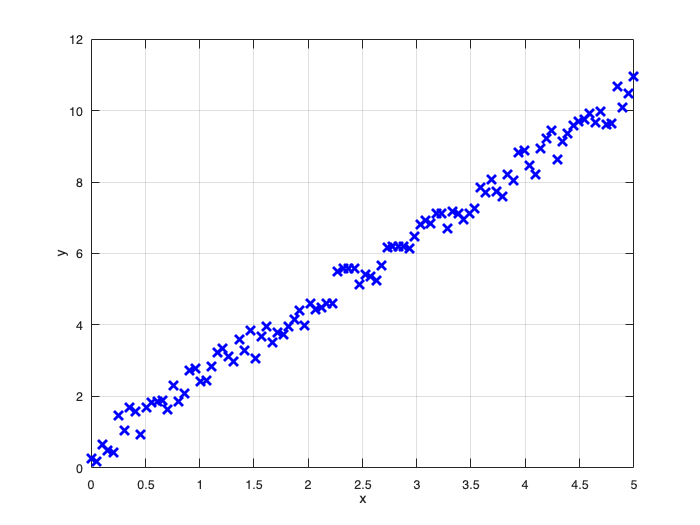

clear; clf; 
m = 2; b = 0.5;
x = linspace(0,5,100);
y = addrandomfluctuations(x,m,b,1);
plot(x,y,'bx','MarkerSize',10, 'LineWidth',2)
xlabel('x'); ylabel('y');
% axis([0 0.5 0 2])
grid on

*Figure 2.1. A data set that forms a straight line.*

## The Cost Function

The cost function describes is a measure of the error between the expected value and the measured value. The higher the error, the more it "costs" to correct the error. Thus, the goal is to minimize the error, and therefore, the cost function. 

### The Data Set vs The Best Fit Line

Consider the linear given data set plotted against the best fit line. For this example, the cost function, $J\left(\theta_0 ,\theta_1 \right)$, is given by the expression


$$J\left(\theta_0 ,\theta_1 \right)=\frac{1}{2n}\sum_{i=1}^n {\left\lbrack \left(\theta_0 +\theta_1 x_i \right)-y_i \right\rbrack }^2$$


where $\theta_0 +\theta_1 x_i$ is the equation of the best fit line described by its slope, $\theta_1$, and y-intercept, $\theta_0$, and $y_i$ is the measured value at the $i^{\textrm{th}}$ data point. Thus, the term in the square brackets $\left(\theta_0 +\theta_1 x_i \right)-y_i$ corresponds to the difference between the best fit line and the measured values. When the cost function is minimized, we have the optimum value for the slope, $\theta_1$, and y-intercept, $\theta_0$, and the term $\left(\theta_0 +\theta_1 x_i \right)-y_i$ is small as it could be for each data point. In Figure 2.2, the term $\left(\theta_0 +\theta_1 x_i \right)-y_i$ is the value between each of the blue crosses and the value of the best fit line corresponding to $x_i$.

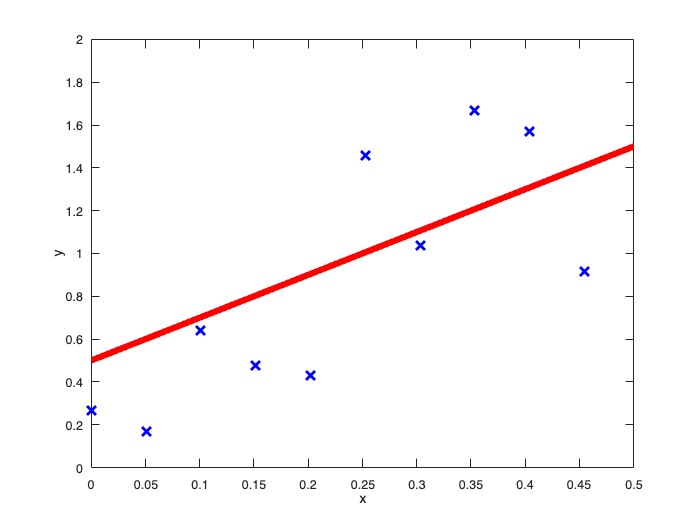

plot(x,y,'bx','MarkerSize',10, 'LineWidth',2)
hold on
ylr = addrandomfluctuations(x,m,b,0.0);
plot(x,ylr, 'r', 'LineWidth',5)
xlabel('x'); ylabel('y');
axis([0 0.5 0 2])
hold off

*Figure 2.2. The difference between the blue crosses and the red line at each data point, *$x_i$, corresponds to the term $\left(\theta_0 +\theta_1 x_i \right)-y_i$.

Let's also display the first few data points by assigning the datasets to a table.

T = table(x',y','VariableNames',{'X Data', 'Y Data'})

T = 100×2 table
     X Data     Y Data 
    ________    _______

           0    0.26487
    0.050505    0.16937
     0.10101    0.63835
     0.15152    0.47688
     0.20202    0.43015
     0.25253     1.4597
     0.30303     1.0367
     0.35354     1.6686
     0.40404     1.5705
     0.45455    0.91644
     0.50505     1.6901
     0.55556     1.8171
     0.60606     1.8572
     0.65657     1.8654
     0.70707     1.6323
     0.75758     2.2875


### The Cost Function in 2D vs The Best Fit Line

Let's try to understand what is happening here and what it means to our data when we minimize one of these parameters. Let's set the y-intercept to $\theta_0 =0\ldotp 5$ and then vary the slope of the line, $\theta_1$. While we vary the slope, we take a look at the cost function.

Watch this video and try to figure out what the value of $\theta_1$ is that minimizes the cost function. The function *costfunction_2D()* is defined at the end of this script. Here the y-intercept is fixed and the slope is varied. So, the red line is fixed at one end and just sweeps over an area on the graph eventually passing through all the data points neatly, which corresponds to when the cost function has a minimum value.

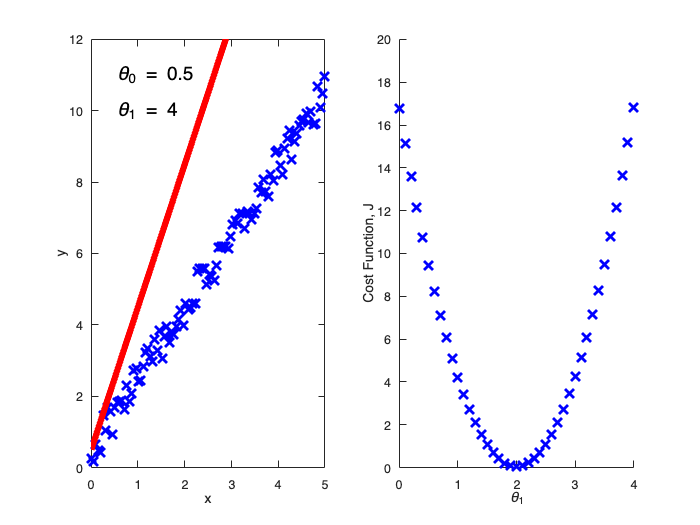

theta0 = 0.5;
theta1 = 0:0.1:4;
time = 0.2;

[~,~,J] = costfunction(x,y,theta0,theta1);
plot_costfunction_2D(x,y,theta0,theta1,J,time);

*Video 2.1. As the value of *$\theta_1$* varies from 0 to 4, we see the red line slowly becoming closer to the blue data points until it fits nicely. This corresponds to the minimum value of the cost function.*

We can observe the same thing if we set the slope $\theta_1 =2$ and vary the y-intercept, $\theta_0$.

Watch this video and try to figure out what the value of $\theta_1$ is that minimizes the cost function. Here the slope is fixed and the y-intercept is varied. So, the red line slowly rises from a low y-intercept value to a high y-intercept value. At some value $\theta_0$, the red line passes through all the points neatly, which corresponds to when the cost function has a minimum value.

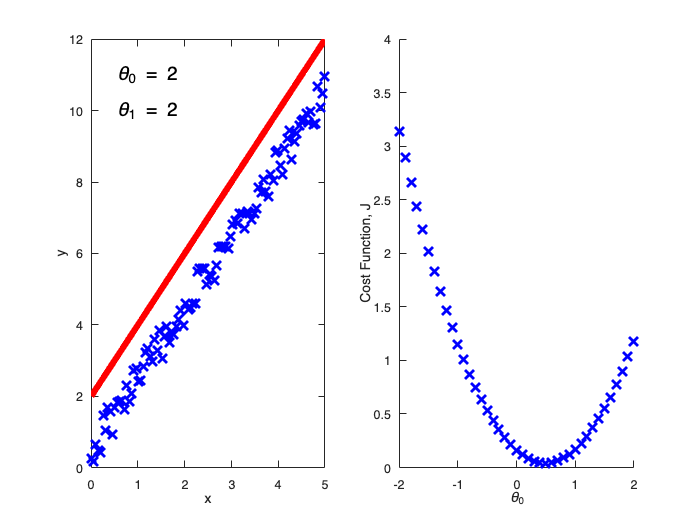

theta0 = -2:0.1:2;
theta1 = 2;
time = 0.2;

[~,~,J] = costfunction(x,y,theta0,theta1);
plot_costfunction_2D(x,y,theta0,theta1,J,time);

*Video 2.2. As the value of *$\theta_0$* varies from -2 to 2, we see the red line slowly becoming closer to the blue data points until it fits nicely. This corresponds to the minimum value of the cost function.*

### The Cost Function in 3D vs The Best Fit Line

Now, let's take a look at the full 3D image of the cost function. In other words, we plot the cost function, $J\left(\theta_0 ,\theta_1 \right)$ against both $\theta_0$ and $\theta_1$, and then compare it with how the red line fits the data set.

First, let's take a look at where the minimum value of the cost function is. The black dot on the cost function graph depicts this minimum value.

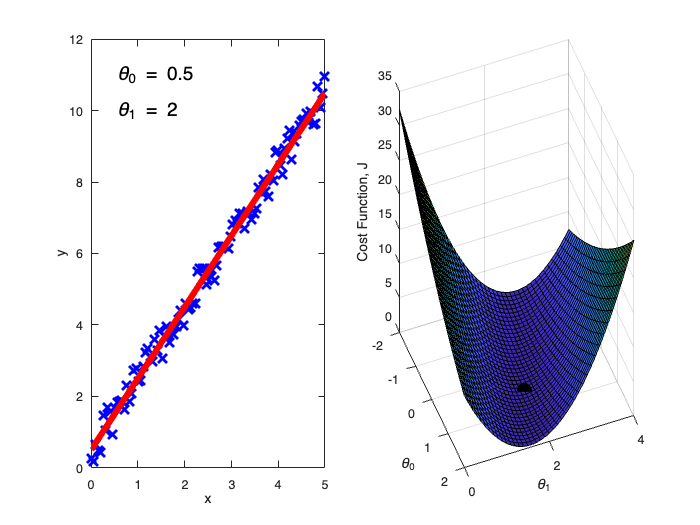

% initial values (non-varying)
theta0 = -2:0.1:2;
theta1 = 0:0.1:4;
init0 = 0.5;
init1 = 2;
time = 0.2;

[~,~,J] = costfunction(x,y,theta0,theta1);
plot_costfunction_3D(x,y,theta0,theta1,J,init0,init1,time);

*Video 2.3. The location of the minimum value and the best fit line for the given data set.*

Now, we fix the y-intercept, $\theta_0$, and allow the slope, $\theta_1$ to vary. The black dot on the 3D plot of the cost function corresponds to the various values of the y-intercept and the slope.

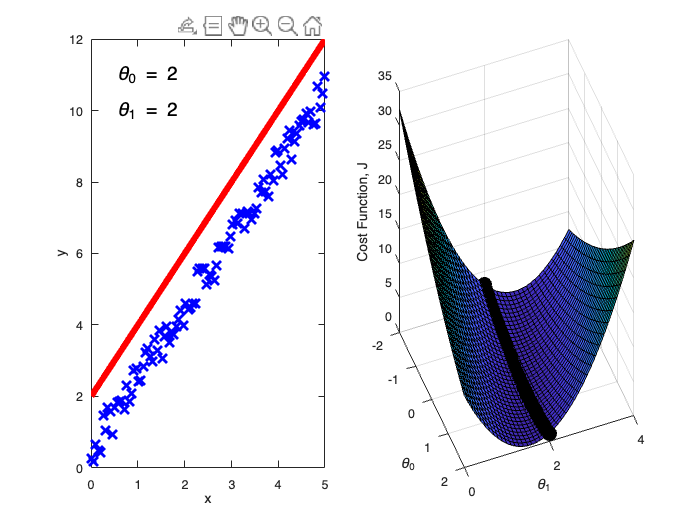

% initial values (varying theta0)
init0 = -2:0.1:2;
init1 = 2;
time = 0.2;

[~,~,J] = costfunction(x,y,theta0,theta1);
plot_costfunction_3D(x,y,theta0,theta1,J,init0,init1,time);

*Video 2.4. The various values of the slope, *$\theta_1$*, with a fixed y-intercept, *$\theta_0$* in relation to the fitting line.*

We now vary the y-intercept, $\theta_0$, and fix the slope, $\theta_1$ to a specific value. The black dot on the 3D plot of the cost function corresponds to the various values of the y-intercept and the slope.

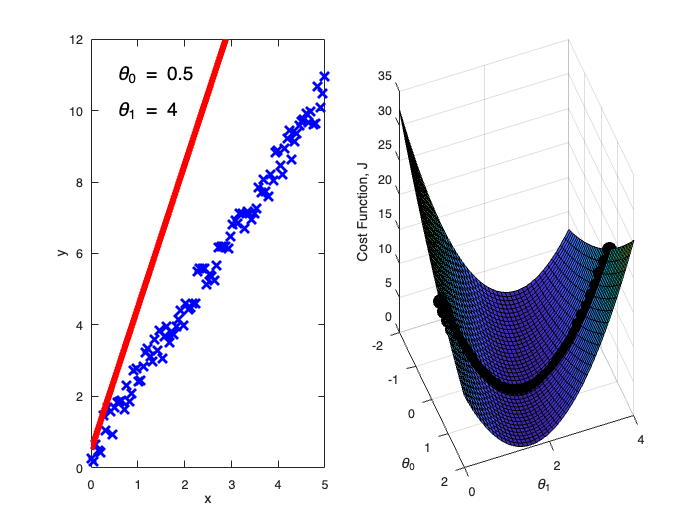

% initial values (varying theta1)
init0 = 0.5;
init1 = 0:0.1:4;
time = 0.2;

[~,~,J] = costfunction(x,y,theta0,theta1);
plot_costfunction_3D(x,y,theta0,theta1,J,init0,init1,time);

*Video 2.5. The various values of the y-intercept, *$\theta_0$, *with a fixed slope, *$\theta_1$*, in relation to the fitting line.*

## The Derivative of the Cost Function

How do we determine the minimum value of the cost function? We use gradient descent to determine the fastest way to the minimum value from a given set of initial parameters or initial guesses. To perform gradient descent, we need to take the derivative of the cost function with respect to the parameters, $\theta_0$ and $\theta_1$. We get the following expressions:

$\frac{\partial J\left(\theta_0 ,\theta_1 \right)}{\partial \theta_0 }=\frac{1}{n\;}\sum_{i=1}^n \left\lbrack \left(\theta_0 +\theta_1 x_i \right)-y_i \right\rbrack$ and $\frac{\partial J\left(\theta_0 ,\theta_1 \right)}{\partial \theta_1 }=\frac{1}{n\;}\sum_{i=1}^n \left\lbrack \left(\theta_0 +\theta_1 x_i \right)-y_i \right\rbrack x_i$.

These derivatives point towards the greatest change in the cost function along the direction of the parameters. Thus, in one iteration, we get a new guess for the optimum value by subtracting these values from the initial guesses. In other words,

$\theta_0 -\alpha \frac{\partial J\left(\theta_0 ,\theta_1 \right)}{\partial \theta_0 }\;\;\to \;\;\theta_0$ and $\theta_1 -\alpha \frac{\partial J\left(\theta_0 ,\theta_1 \right)}{\partial \theta_1 }\;\;\to \;\;\theta_1$.

Using those new values, we get a new set of gradients, which we then subtract again from these new guesses to get a third guess. We do this iteratively until the gradient becomes very small or until after a specified number of iterations. The implementation of the gradient descent can be seen in the *gradient_descent()* function at the end of the script.

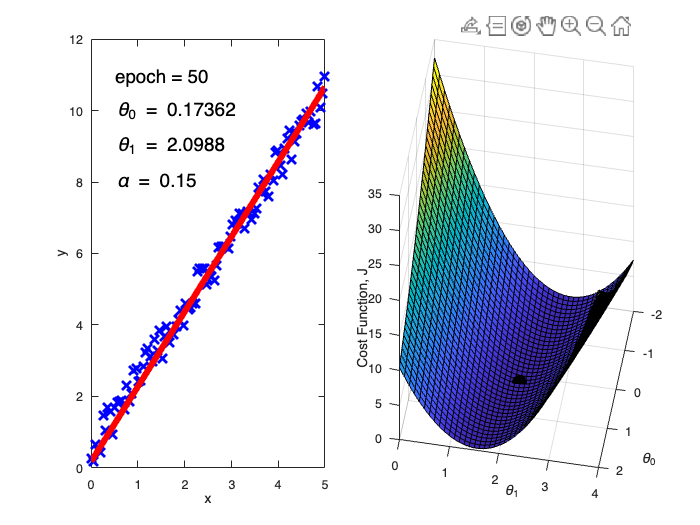

iter = 51;
learning_rate = 0.15;       

init0 = -2;     % possible values -2:0.1:2
init1 = 0;      % possible values 0:0.1:4

[~,~,~,~,J_cost] = gradient_descent(x,y,init0,init1,iter,learning_rate,time);

*Video 2.6. Using gradient descent to determine the optimum value of the cost function.*

We can plot the cost function and see how it decreases per iteration.

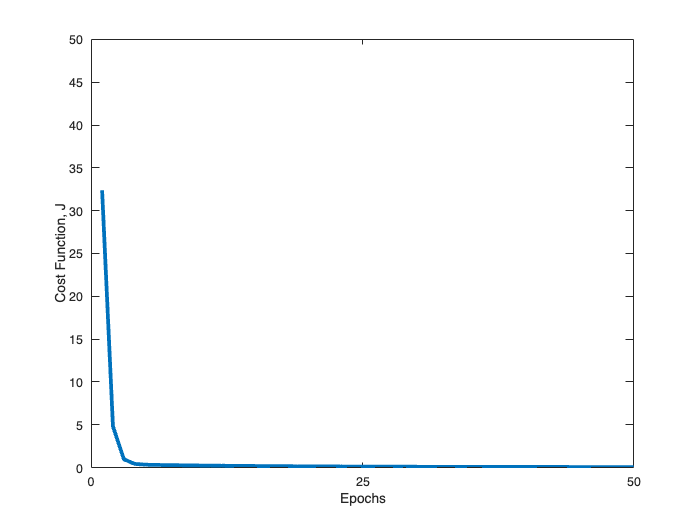

figure
plot(J_cost,'LineWidth',3)
xlabel('Epochs')
ylabel('Cost Function, J')
ylim([0 50])
xticks([0 25 50 75 100 125 150])

*Figure 2.3. The decrease of the cost function is seen with the number of iterations or epochs*.

## The Learning Rate

The basic algorithm for the gradient descent can be written as

$\textrm{iterate}\;{\left\lbrace \theta_i -\alpha \frac{\partial J\left(\theta_0 ,\theta_1 \right)}{\partial \theta_i }\;\;\to \;\;\theta_i \right\rbrace }_{i=0,1} \;$.

You might notice that there is a parameter, $\alpha$. This parameter is called a learning rate. It's a parameter that when properly chosen, the function converges to the optimum value quickly. Otherwise, the convergence will be too slow or it might not converge at all. Using the same code we used earlier, try to change the learning rate to a smaller value and then to a larger value to see what happens.

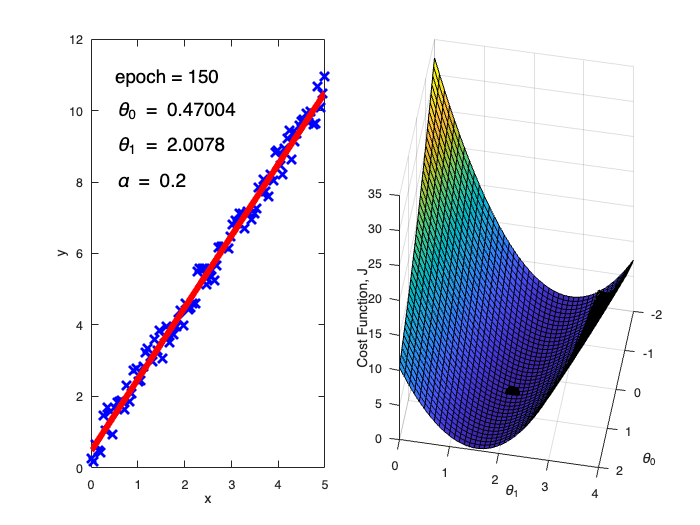

iter = 151;
learning_rate = 0.2;       

init0 = -2;     % possible values -2:0.1:2
init1 = 0;      % possible values 0:0.1:4

[~,~,~,~,J_cost] = gradient_descent(x,y,init0,init1,iter,learning_rate,time);

*Video 2.7. Using gradient descent to determine the optimum value of the cost function.*

In choosing the learning rate, you want a relatively smooth decrease of the cost function with the number of iterations.

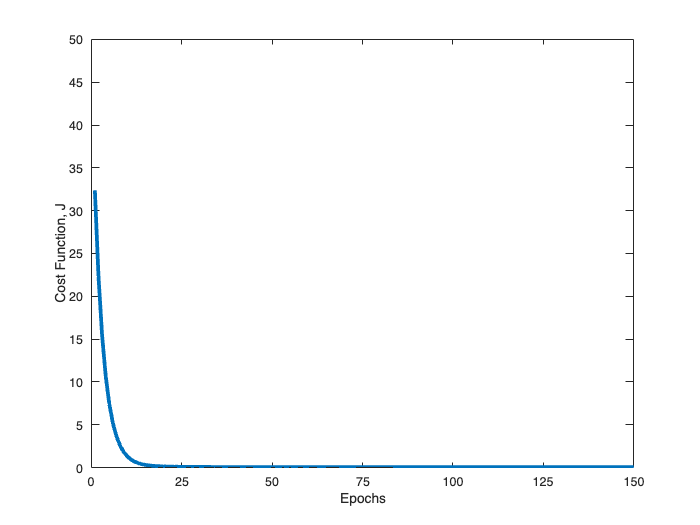

figure
plot(J_cost,'LineWidth',3)
xlabel('Epochs')
ylabel('Cost Function, J')
ylim([0 50])
xticks([0 25 50 75 100 125 150])

*Figure 2.4. The decrease of the cost function is seen with the number of iterations or epochs*.

## Functions Used

### Function that adds random values

This function adds random values to the vertical axis so that the data set looks random.

function yrand = addrandomfluctuations(x,m,b,fluctuationsize)
    for i = 1:length(x)
        yrand(i) = m*x(i) + b + fluctuationsize*(rand(1)-0.5);
    end
end


### Function for the Cost Function

This function computes the cost function with input arguments $x$, $y$, $\theta_0$, and $\theta_1$.

function [th0,th1,J] = costfunction(x,y,th0,th1)
    n = length(y);

    for i = 1:length(th0)
        for j = 1:length(th1)
            J(i,j) = (1/(2*n))*sum((th0(i) + th1(j)*x - y).^2);
        end
    end
end

%% function that plots the cost function in 2D
function plot_costfunction_2D(x,y,th0,th1,J,time)
    clf
    [~,w0] = size(th0);

    for i = 1:length(th0)
        for j = 1:length(th1)
            subplot(1,2,1)
            plot(x,y,'bx','MarkerSize',10, 'LineWidth',2)
            ylr = addrandomfluctuations(x,th1(j),th0(i),0.0);
            hold on
            plot(x,ylr, 'r', 'LineWidth',5)
            xlabel('x'); ylabel('y');
            axis([0 5 0 12])
            text(0.5,11,['\theta_0 = ', num2str(th0(i))], 'FontSize',15)
            text(0.5,10,['\theta_1 = ', num2str(th1(j))], 'FontSize',15)
            hold off

            subplot(1,2,2)
            hold on
            if w0 == 1
                plot(th1(j),J(1,j),'bx','MarkerSize',10, 'LineWidth',2);
                xlabel('\theta_1'); ylabel('Cost Function, J');
                axis([0 4 0 20])
            else
                plot(th0(i),J(i,1),'bx','MarkerSize',10, 'LineWidth',2);
                xlabel('\theta_0'); ylabel('Cost Function, J');
                axis([-2 2 0 4])
            end
            pause(time)
        end
    end
end

### Function for Plotting the Cost Function

This function plots the cost function in 3D. 

function plot_costfunction_3D(x,y,theta0,theta1,J,th0,th1,time)
    clf
    n = length(y);

    for i = 1:length(th0)
        for j = 1:length(th1)
            subplot(1,2,1)
            plot(x,y,'bx','MarkerSize',10, 'LineWidth',2)
            ylr = addrandomfluctuations(x,th1(j),th0(i),0.0);
            hold on
            plot(x,ylr, 'r', 'LineWidth',5)
            xlabel('x'); ylabel('y');
            axis([0 5 0 12])
            text(0.5,11,['\theta_0 = ', num2str(th0(i))], 'FontSize',15)
            text(0.5,10,['\theta_1 = ', num2str(th1(j))], 'FontSize',15)
            hold off

            subplot(1,2,2)
            surf(theta0,theta1,transpose(J))
            hold on
            [~,~,Jcost] = costfunction(x,y,th0(i),th1(j));
            plot3(th0(i), th1(j), Jcost,'ko','MarkerSize',10,'LineWidth',2,'MarkerFaceColor','k')
            xlabel('\theta_0')
            ylabel('\theta_1')
            zlabel('Cost Function, J')
            view([69 31])
        
            pause(time)
        end
    end

end

### Function for the Computing the Gradient Descent

This function solves for the gradient and uses the gradient to determine the optimum value from an initial set of values. The parameter, *alpha*, is the learning rate. The parameter, *iter*, is the number of epochs.

function [t0,t1,gradJcost0,gradJcost1,Jcost] = gradient_descent(x,y,init0,init1,iter,a,time)
    t0 = zeros(1,iter);
    t1 = zeros(1,iter);
    t0(1) = init0;
    t1(1) = init1;

    n = length(y);   
    theta0 = -2:0.1:2;
    theta1 = 0:0.1:4;
    [~,~,J] = costfunction(x,y,theta0,theta1);

    for i = 1:iter-1

        subplot(1,2,1)
        plot(x,y,'bx','MarkerSize',10, 'LineWidth',2)
        hold on
        ylr = addrandomfluctuations(x,t1(i),t0(i),0.0);
        plot(x,ylr, 'r', 'LineWidth',5)
        xlabel('x'); ylabel('y');
        text(0.5,11,['epoch = ', num2str(i)], 'FontSize',15)
        text(0.5,10,['\theta_0 = ', num2str(t0((i)))], 'FontSize',15)
        text(0.5,9,['\theta_1 = ', num2str(t1((i)))], 'FontSize',15)
        text(0.5,8,['\alpha = ', num2str(a)], 'FontSize',15)
        hold off

        subplot(1,2,2)
        surf(theta0,theta1,transpose(J))
        hold on
        [~,~,Jcost(i)] = costfunction(x,y,t0(i),t1(i));
        plot3(t0(i), t1(i), Jcost(i),'ko','MarkerSize',10,'LineWidth',2,'MarkerFaceColor','k')
        xlabel('\theta_0')
        ylabel('\theta_1')
        zlabel('Cost Function, J')
        view([100 33])
        hold off

        % Solve for the derivative
        gradJcost0(i) = (1/n)*sum(t0(i) + t1(i)*x - y);
        gradJcost1(i) = (1/n)*sum((t0(i) + t1(i)*x - y).*x);

        % Get new values of the parameters
        t0(i+1) = t0(i) - a*gradJcost0(i);
        t1(i+1) = t1(i) - a*gradJcost1(i);

        pause(time)
    end
end